%% Gs=(1+N/10)/((s+1)*(s+5))
%ts<=1; Wd>=2; Kv>=20; 
clc
clear
close all
N=4;
s=tf('s');
Gs=(1+N/10)/((s+1)*(s+5)) %aplicamos un integrador para disminuir el error de posicion

Gs =
 
       1.4
  -------------
  s^2 + 6 s + 5
 
Continuous-time transfer function.



ProcentajeCriterioTs=0.02;
CriterioRiso=[0.10 0.90];
ParametroSys(feedback(Gs,1),ProcentajeCriterioTs,CriterioRiso) %el sistema es inestable en LO no se analiza mas nada

                                                           
   Pole        Damping       Frequency      Time Constant  
                           (rad/seconds)      (seconds)    
                                                           
 -1.39e+00     1.00e+00       1.39e+00         7.21e-01    
 -4.61e+00     1.00e+00       4.61e+00         2.17e-01    


Resultados =     '
     Ts(2.00)=3.0773
     Tr=1.6996
     Mp=0.0000
     Tp=5.3715
     Tao=0.6690
     ValorF=0.2187
     '


ans = 3.0773

[Ep,Ev,Ea,Kp,Kv,Ka]=ErroEpEvEa(Gs);
Kv=1/Ev

Kv = 0

% figure(1)
% step(feedback(Gs,1))
%figure(2)
%rlocus(Gs)

 % subplot(221),rlocus(Gs)
% subplot(223),nyquist(Gs)
% subplot(122),margin(Gs)

%% Calcular polos deseados y posicion
clc
close all
Ts=1; Wd=2.6; Kv=20; %agrego un polo en el origen apra cumplir con Kv
Sigma=4/Ts

Sigma = 4

Mp=exp(-pi*Sigma/Wd)

Mp = 0.0080

Wn=sqrt(Sigma^2+Wd^2)

Wn = 4.7707

Zeta=Sigma/Wn

Zeta = 0.8384

rlocus(Gs),sgrid(Zeta,0)
[Phi,C]=LeadLGR(Gs,Sigma,Wd,0) %%red de adelanto

Phi = 28.0481

C =
 
  9.1625 (s+4.113)
  ----------------
     (s+5.534)
 
Continuous-time zero/pole/gain model.



%% 
clc
close all
s=tf('s');
GsC=C*Gs;
Tc=feedback(GsC,1); %sistema controlado
Tk=feedback(Gs,1);
% Su=feedback(C,Gs); %señal de control
% figure(2)
% subplot(121),step(Tc,Tk),legend
% subplot(122),step(Su),legend
% %subplot(133),margin(Tk)
% figure(3)
% rlocus(GsC)
%% Red en atraso
clc
s=tf('s');
%%error del sistema 
ProcentajeCriterioTs=0.02;
CriterioRiso=[0.10 0.90];
ParametroSys(Tc,ProcentajeCriterioTs,CriterioRiso)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -3.53e+00                 1.00e+00       3.53e+00         2.83e-01    
 -4.00e+00 + 2.60e+00i     8.38e-01       4.77e+00         2.50e-01    
 -4.00e+00 - 2.60e+00i     8.38e-01       4.77e+00         2.50e-01    


Resultados =     '
     Ts(2.00)=0.9909
     Tr=0.6127
     Mp=0.1186
     Tp=1.4596
     Tao=0.2154
     ValorF=0.6560
     '


ans = 0.9909

%% Error y polos del sistema
clc
Kvd=20; % requisito
%sx=pole(Tc)
sx=-Sigma+Wd*j

sx = -4.0000 + 2.6000i

Z=-real(sx)/10 %una decima del valor deseado

Z = 0.4000

[Ep,Ev,Ea,Kp,Kv,Ka]=ErroEpEvEa(GsC);
Kv=1/Ev

Kv = 0

Beta=Kvd/Kv

Beta = Inf

P=Z/Beta

P = 0

s=sx;
C1=(s+Z)/(s+P);
Gss=tf2sym(GsC);
Kc1=abs(eval(1/(Gss*C1)))+1

Kc1 = 2.0743

RelaAngulo=radtodeg(angle(Kc1*C1))

RelaAngulo = -2.8138

s=tf('s');
C1=(s+Z)/(s+P)

C1 =
 
  s + 0.4
  -------
     s
 
Continuous-time transfer function.



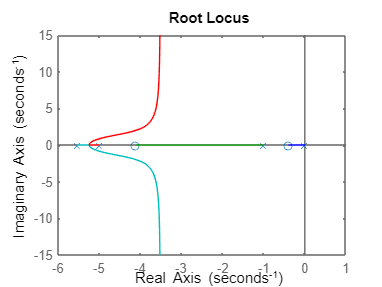

%% Comprobar controlador
clc
close all
%C=51.699*(s+3.892)/(s+16.12)
GsC1=C1*GsC;
rlocus(GsC1)

Tc=feedback(GsC1,1); %sistema controlado
Tk=feedback(GsC,1);
Su=feedback(C,GsC1); %señal de control
ParametroSys(Tc,ProcentajeCriterioTs,CriterioRiso)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -2.95e-01                 1.00e+00       2.95e-01         3.39e+00    
 -3.38e+00                 1.00e+00       3.38e+00         2.96e-01    
 -3.93e+00 + 2.39e+00i     8.54e-01       4.60e+00         2.54e-01    
 -3.93e+00 - 2.39e+00i     8.54e-01       4.60e+00         2.54e-01    


Resultados =     '
     Ts(2.00)=9.1455
     Tr=3.5464
     Mp=0.0000
     Tp=23.8780
     Tao=1.9881
     ValorF=1.0000
     '


ans = 9.1455

[Ep,Ev,Ea,Kp,Kv,Ka]=ErroEpEvEa(GsC1);
KvF=1/Ev

KvF = 0.7627

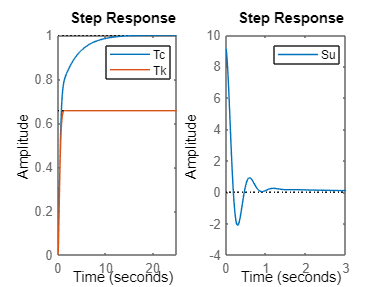

subplot(121),step(Tc,Tk),legend
subplot(122),step(Su),legend